# Solution to the *Clustering Futures Contracts *exercise

## 1. Load data

Load the data in `contractData.mat`.

load contractData

This file contains a table, data, with 14 variables. The first column contains the time stamp and the remaining variables represent volume observations of 13 futures contracts.  

## 2. Extract numeric data and labels

Extract the data labels and create a matrix of the numeric volume data from the table, excluding the time stamp.

labels = data.Properties.VariableNames(2:end);
voldata = data{:,2:end};

## 3. Hierarchical clustering

Use hierarchical clustering to examine the correlation between groups of contracts. First, take the transpose of the numeric data. Then, find the linkage using the single clustering method and correlation distance metric.  

voldata = voldata';
Z = linkage(voldata,'single','correlation');

## 4. Create dendrogram

Create a dendrogram to visualize the hierarchy. Capture the order of the node labels as an output argument from the `dendrogram` function. 

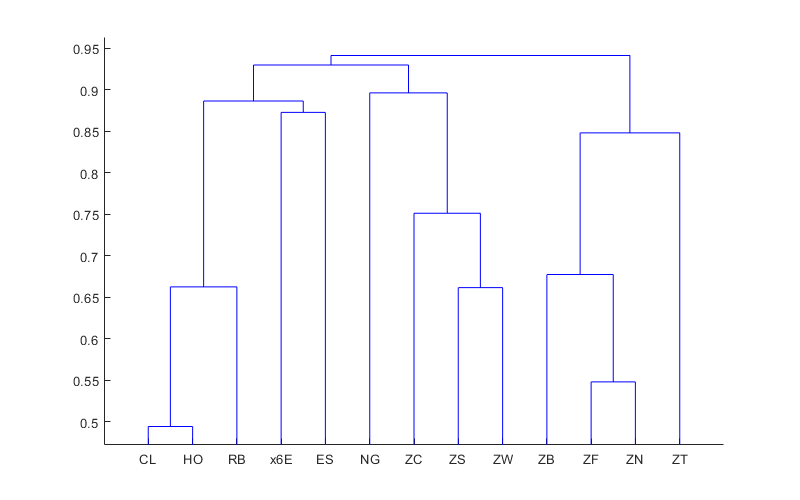

[~,~,ind] = dendrogram(Z,0,'labels',labels);

## 5. Visualize correlation between groups with heatmap

Visualize the correlation between groups of contracts with a heatmap. 

**Hint: **Determine the correlation coefficients between the variables and use the order of labels from step 4 to group the variables in the image. 

c = corrcoef(data{:,2:end});

Remove diagonals for visualization

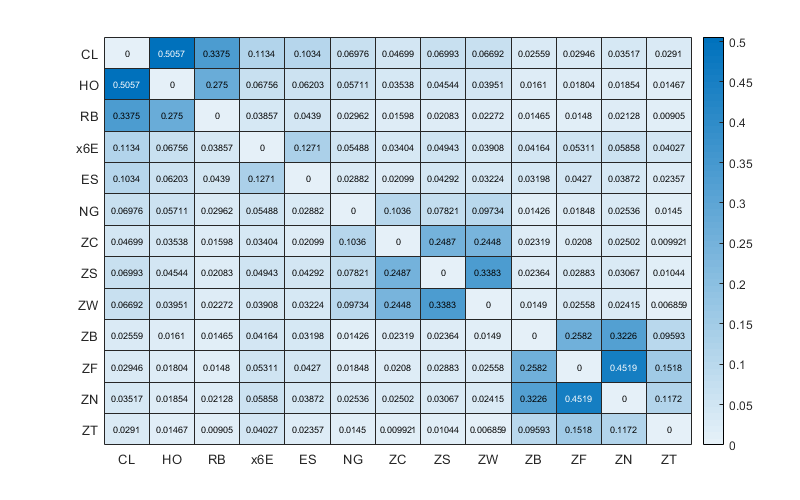

cviz = c - diag(diag(c));
heatmap(labels(ind),labels(ind),cviz(ind,ind));